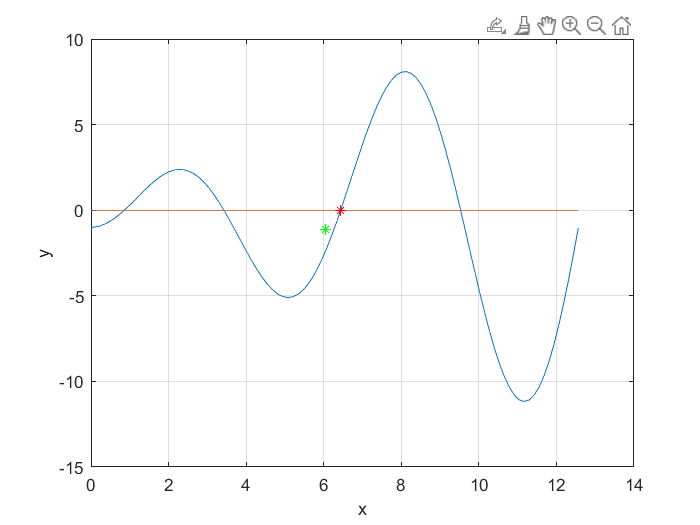

a = 0;
b = 4*pi;
m = 100;
x = linspace(a,b,m);
f = 'x.*sin(x)-cos(x)';
plot(x,eval(f),x,0*x);
grid on;
xlabel('x');
ylabel('y');

z = ginput(1);
[zr,fr]=fzero(f,z(1));

hold on;
plot(zr,fr,'r*',z(1),z(2),'g*');


zr

zr = 6.4373

fr

fr = -2.1094e-15


syms y;

'syms' requires Symbolic Math Toolbox.

Eq = y.*sin(y)-cos(y)==0;
j = vpaslove(Eq,y);
j

task_2_newton();


function [tt, to_break] = check_root(f, x, epsil)
    tt = f(x);
    to_break = false;
    if abs(tt) < epsil
        hold on
        plot(x, tt, 'g.', MarkerSize=20)
        hold off
        to_break = true;
    end
end

function task_2_newton()
    [x_, y, y1] = plot_task_2();
    max_iter = 40;
    h = 1e-6;
    while true
        z = ginput(1);
        x = z(1);
        x_sol = fzero(@bar, x);
        skip_zs = false;
        for j = 1:max_iter
            [tt, to_break] = check_root(@bar, x, 1e-10);
            if to_break
                break
            end
            x_next = x - h*tt/(bar(x + h) - tt);
            hold on
            plot([x, x_next], [tt, bar(x_next)], 'r')
            hold off
            if ~skip_zs
                z = ginput(1);
                if z(2) < 0
                    skip_zs = true;
                end
            end
            plot(x_, y, x_, y1, ':')
            x = x_next;
        end
        disp(abs(x_sol-x))
    end
end

function [x, y, y1] = plot_task_2()
    fr = 0;
    to = 7;
    x = linspace(fr, to, 1000);
    y = bar(x);
    y1 = 0*x;
    plot(x, y, x, y1, ':');
end



function res = bar(x)
    res = sin(x)./x
end